# Generate Accelerometer Data from Stationary Inputs

Generate accelerometer data for an imuSensor object from stationary inputs.

Generate an accelerometer parameter object with a maximum sensor reading of 19.6 $\mathrm{m}/{\mathrm{s}}^2$ and a resolution of 0.598 $\left(\textrm{mm}/{\mathrm{s}}^2 \right)/\textrm{LSB}$. The constant offset bias is 0.49 ${\rm{m/}}{{\rm{s}}^{\rm{2}}}$. The sensor has a power spectral density of 3920 $\left(\mu \mathrm{m}/{\mathrm{s}}^2 \right)/\sqrt{\textrm{Hz}}$. The bias from temperature is 0.294 $\left(\mathrm{m}/{\mathrm{s}}^2 \right)$${\rm{/}}{}^{\rm{0}}{\rm{C}}$. The scale factor error from temperature is 0.02%${\rm{/}}{}^{\rm{0}}{\rm{C}}$. The sensor axes are skewed by 2%.

% params = accelparams('MeasurementRange',19.6,'Resolution',0.598e-3,'ConstantBias',0.49,'NoiseDensity',3920e-6,'TemperatureBias',0.294,'TemperatureScaleFactor',0.02,'AxesMisalignment',2);
params = accelparams('MeasurementRange',19.6,'Resolution',0.598e-3,'ConstantBias',0.49,'NoiseDensity',3920e-6,'TemperatureBias',0.294,'TemperatureScaleFactor',0.02,'AxesMisalignment',2);

Use a sample rate of 100 Hz spaced out over 1000 samples. Create the imuSensor object using the accelerometer parameter object.

Fs = 100;
numSamples = 1000;
t = 0:1/Fs:(numSamples-1)/Fs;

imu = imuSensor('SampleRate', Fs, 'Accelerometer', params);

Generate accelerometer data from the imuSensor object.

orient = quaternion.ones(numSamples, 1);
acc = zeros(numSamples, 3);
angvel = zeros(numSamples, 3);
 
accelData = imu(acc, angvel, orient);

Plot the resultant accelerometer data.

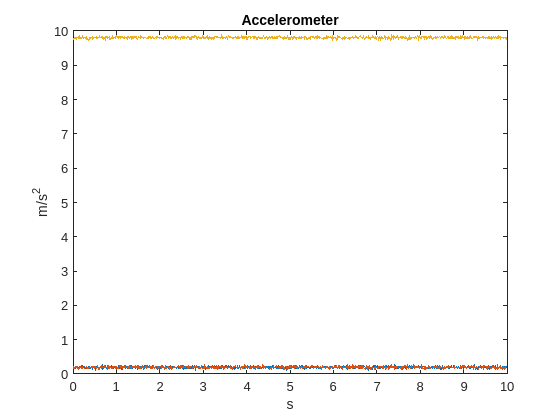

plot(t, accelData)
title('Accelerometer')
xlabel('s')
ylabel('m/s^2')

*Copyright 2018 The MathWorks, Inc.*